# Simulation of money dynamics with N-agents and taxes

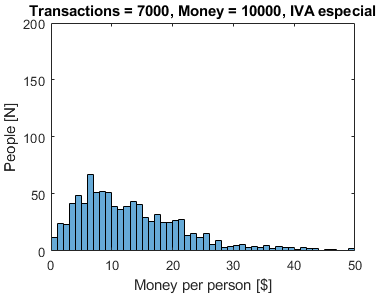

clc; clear; close all

% RESTRICTIONS
N = 1000;                       % Number of agents
M = 1e4;                        % Number of money
n = 7e3;                        % Number of iterations
tax = 0;                        % Initiate tax acumulation
k = 0:50;                       % bins for histograms
IVA = @(m) 0.16*exp(0.08*m);    % Tax collection as function of buyer's money
% IVA = @(m) 0.16*m/m;          % Tax collection as a constant

% VECTORS' INITIATION
m = M/N*ones(N,1);              % Money's vector initiation (equally distributed)
S = nan(n,1);                   % Entropy's vector initiation
Well = nan(n,1);                % Well's vector initiation
percent = round(rand(n,1),10);  % Random percentajes of buyings
par = ceil(N*rand(n,2));        % Initiate random transactions
buy = par(:,1); sell = par(:,2);% Buyers and sellers' assignation

for t = 1:n
    if mod(t,30) == 0; m = m + tax/N; tax = 0; end % Tax distribution rate
    if buy(t) == sell(t); continue; end            % Skip if buyer is the same as seller
    
    % TRANSACTION
    dm = m(buy(t))*percent(t);  % Random transaction from 0 to the total buyer's money
    mtax = IVA(m(buy(t)));      % Money collected by taxes
    tax = tax + mtax*dm;        % Tax acumulation
    m([buy(t) sell(t)]) = [m(buy(t))-dm m(sell(t))+dm*(1-mtax)]; % Money assignation

    % ANIMATION
    histPlot(m,k,t,N,tax,n/100);

    % MEASUREMENT OF WELLNESS AND ENTROPY
    h = histcounts(m,"BinEdges",k); % Histogram's data collection
    S(t) = measureEntrophy(h,N);    % Entropy calculation
    Well(t) = measureWell(h,k);     % Wellness calculation
end

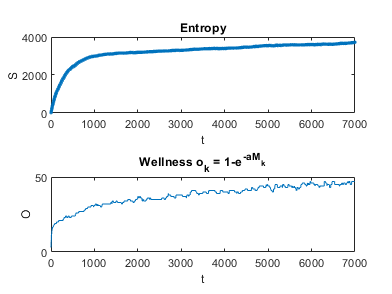


subplot(2,1,1); plot(S,'.'); title('Entropy'); xlabel('t'); ylabel('S')
subplot(2,1,2); plot(Well(Well>0),'-'); title('Wellness o_k = 1-e^{-aM_k}'); xlabel('t'); ylabel('O')

function histPlot(m,k,t,N,tax,velocity)
    if mod(t,velocity) == 0
        clf
        histogram(m,"BinEdges",k);
        title("Transactions = "+num2str(t)+", Money = "+num2str(sum(m)+tax)+", IVA especial")
        ylabel('People [N]'); xlabel('Money per person [$]'); axis([0 50 0 N/5]); 
        drawnow
    end    
end
function S = measureEntrophy(h,N)
    sk = h.*log(h);                 % Entropy calculation's formula (1)
    S = N*log(N)-sum(sk,"omitnan"); % Entropy calculation's formula (2)
end
function Well = measureWell(hist,k)
    a = 1;                          % Arbitary constant
    Mclass = hist.*k(2:end);        % Money in each class
    oclass = 1-exp(-a*Mclass);      % Wellness in each class
    Well = sum(oclass,'omitnan');   % General wellness
end